% Something wrong with pump; replaced pump before cast 9
% no CTD alignment seems to work best? Was there a pump? 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')

% Casts 
cast01 = readSBScnv( 'AR21_001_hyst.cnv' );
cast02 = readSBScnv( 'AR21_002_hyst.cnv');
cast03 = readSBScnv( 'AR21_003_hyst.cnv' );
cast04 = readSBScnv( 'AR21_004_hyst.cnv' );
cast05 = readSBScnv( 'AR21_005_hyst.cnv' );
cast06 = readSBScnv( 'AR21_006_hyst.cnv' );
cast07 = readSBScnv( 'AR21_007_hyst.cnv' );
cast08 = readSBScnv( 'AR21_008_hyst.cnv' );
cast09 = readSBScnv( 'AR21_009_hyst.cnv' );
cast10 = readSBScnv( 'AR21_010_hyst.cnv' );
cast11 = readSBScnv( 'AR21_011_hyst.cnv' );
cast12 = readSBScnv( 'AR21_012_hyst.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
btl = readtable('Irminger_Sea-04_AR21_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year4')

btl07 = readtable('AR21_007_hyst.csv','TextType','string');

btl08 = readtable('AR21_008_hyst.csv','TextType','string');

btl10 = readtable('AR21_010_hyst.csv','TextType','string');

btl11 = readtable('AR21_011_hyst.csv','TextType','string');

btl12 = readtable('AR21_012_hyst.csv','TextType','string');


% Join tables 
btlsum07 = join(btl07,btlsum07,'Keys',"Bottle");
btlsum08 = join(btl08,btlsum08,'Keys',"Bottle");
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");
btlsum11 = join(btl11,btlsum11,'Keys',"Bottle");
btlsum12 = join(btl12,btlsum12,'Keys',"Bottle");

clear btl0* btl1* btl2*

% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.61240e-001);
cal.VOFFSET = double(-5.10000e-001);
cal.A = double(-5.44340e-003);
cal.B = double(3.01750e-004);
cal.C = double(-4.29640e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.04000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0930';
cal.OCALDATE = '11-Nov-16';

H = [-0.033, 5000, 1450]; % Default 

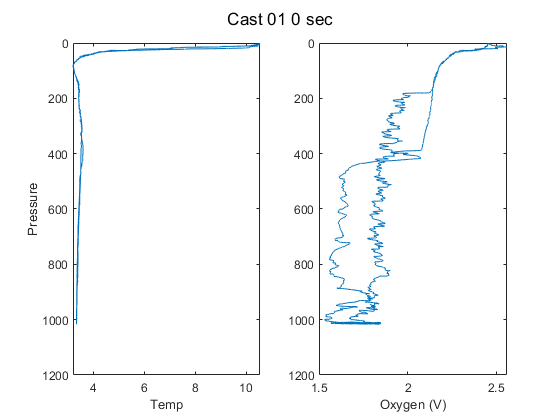

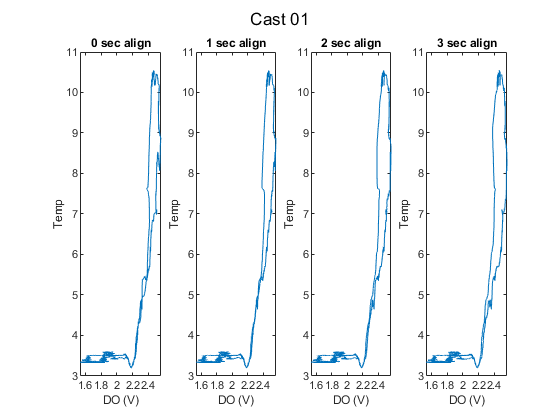

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 1; a2 = 2; a3 = 3;

cast01 = align_CTD_KF(cast01,'Cast 01',a1,a2,a3);

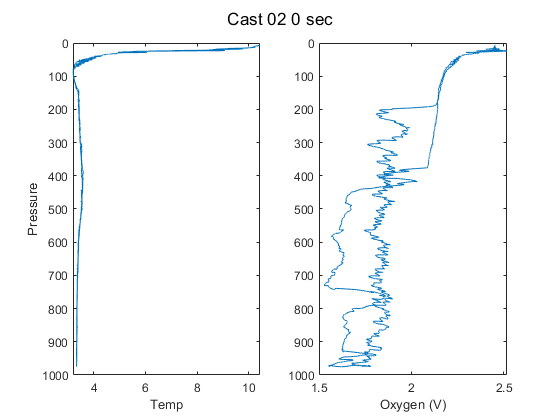

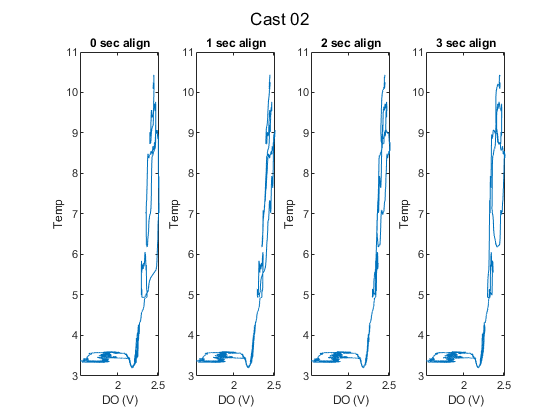

cast02 = align_CTD_KF(cast02,'Cast 02',a1,a2,a3);

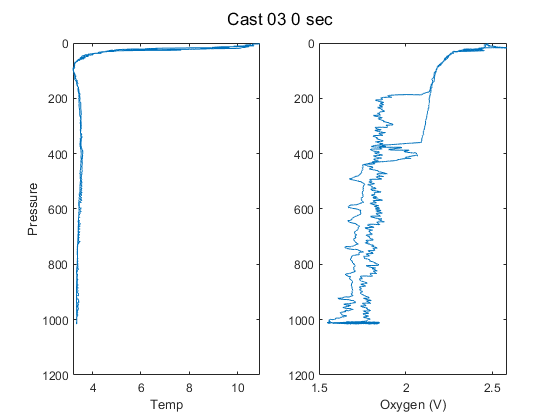

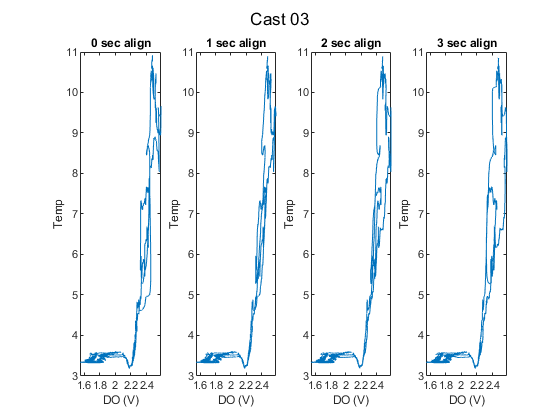

cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);

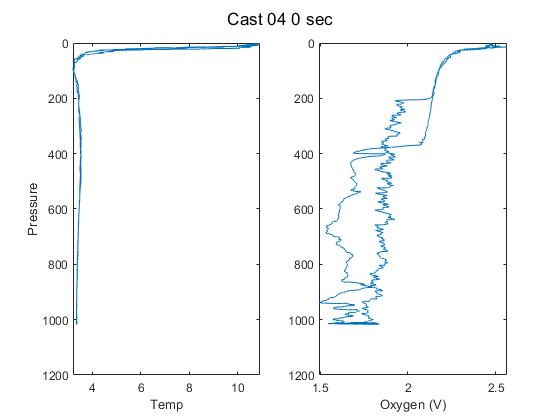

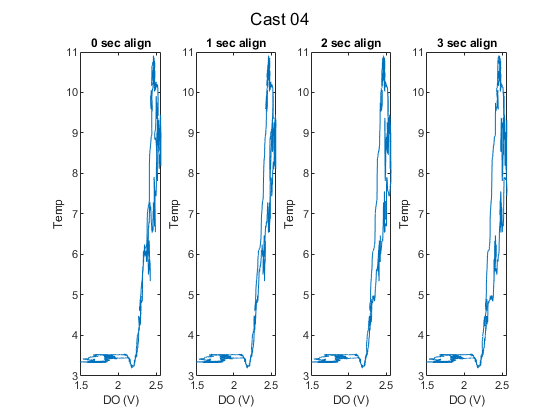

cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);

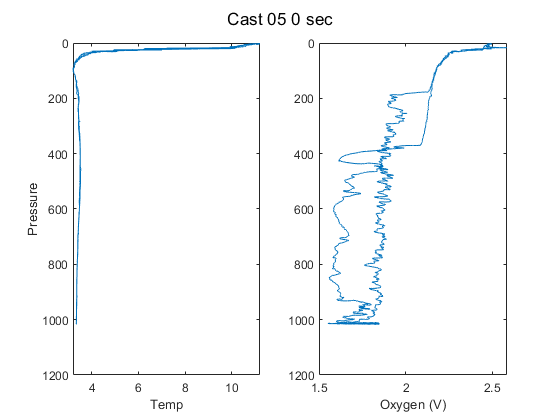

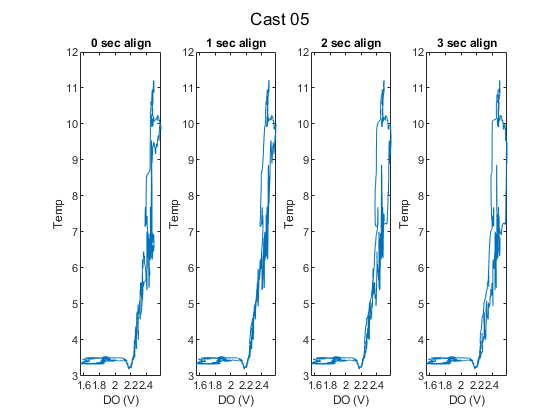

cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);

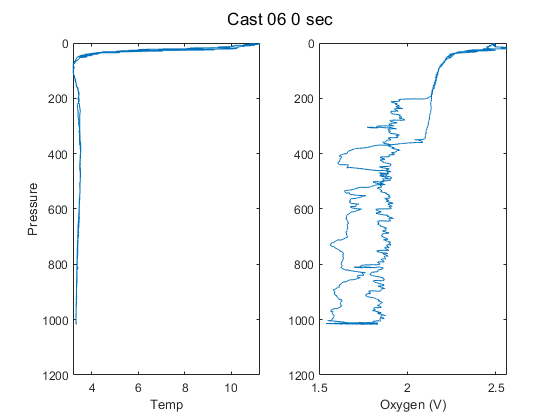

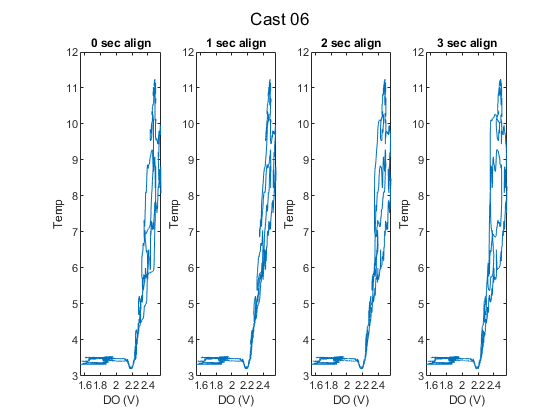

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

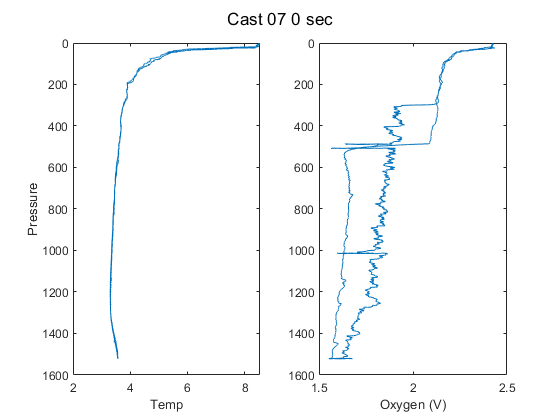

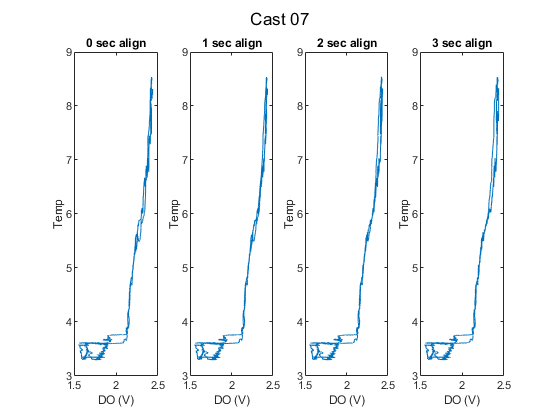

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

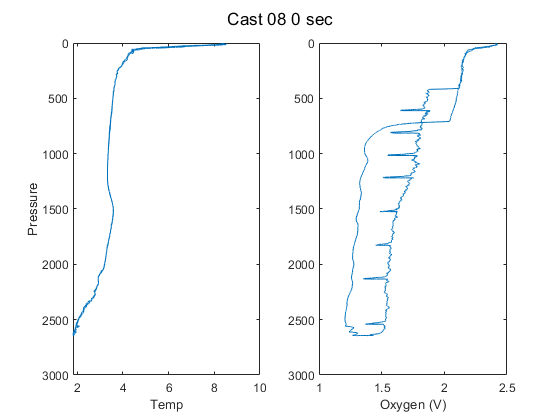

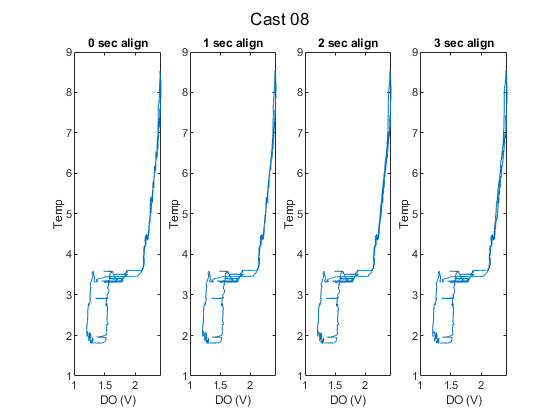

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

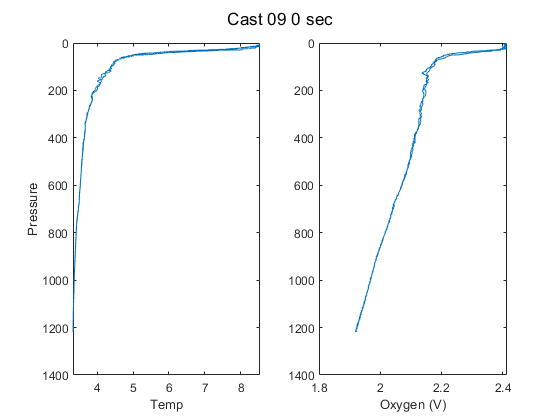

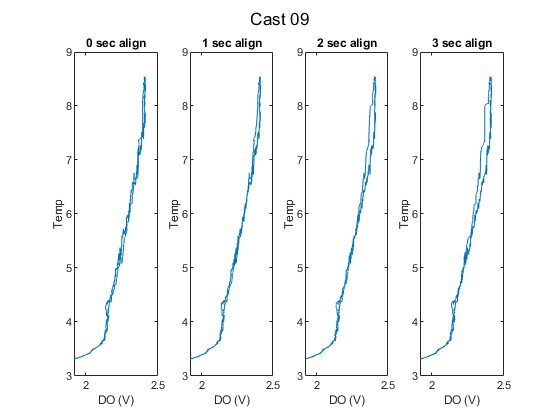

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

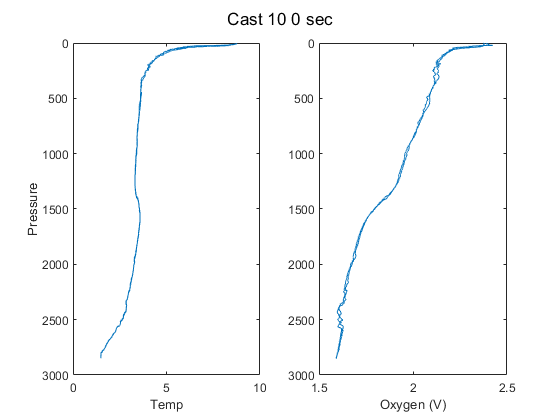

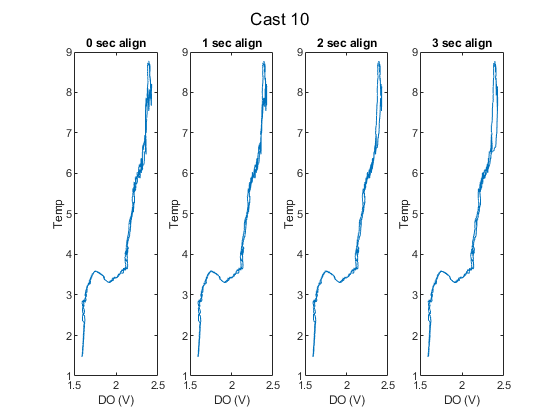

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);

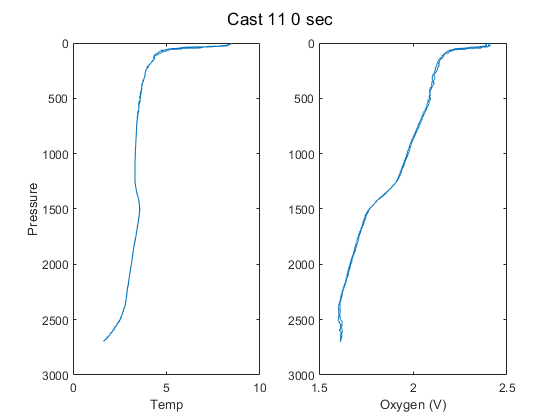

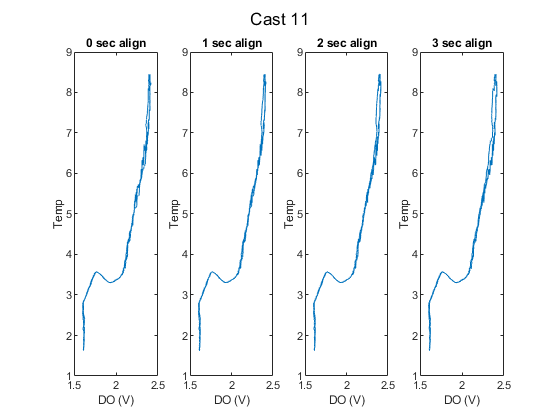

cast11 = align_CTD_KF(cast11,'Cast 11',a1,a2,a3);

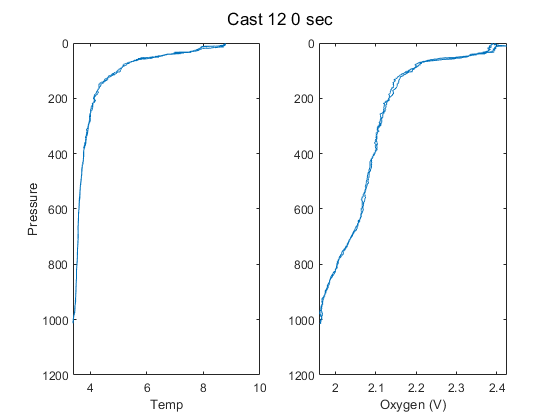

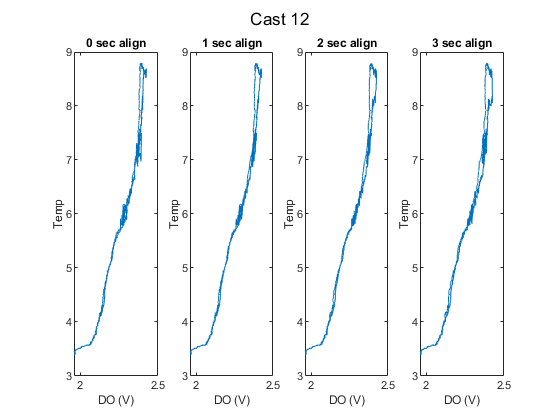

cast12 = align_CTD_KF(cast12,'Cast 12',a1,a2,a3);


% Pick align_sec

align_sec = 0; 

cast01.DOv = SBE_alignCTDW(cast01.sbeox0V, align_sec, 1/24 );
cast02.DOv = SBE_alignCTDW(cast02.sbeox0V, align_sec, 1/24 );
cast03.DOv = SBE_alignCTDW(cast03.sbeox0V, align_sec, 1/24 );
cast04.DOv = SBE_alignCTDW(cast04.sbeox0V, align_sec, 1/24 );
cast05.DOv = SBE_alignCTDW(cast05.sbeox0V, align_sec, 1/24 );
cast06.DOv = SBE_alignCTDW(cast06.sbeox0V, align_sec, 1/24 );
cast07.DOv = SBE_alignCTDW(cast07.sbeox0V, align_sec, 1/24 );
cast08.DOv = SBE_alignCTDW(cast08.sbeox0V, align_sec, 1/24 );
cast09.DOv = SBE_alignCTDW(cast09.sbeox0V, align_sec, 1/24 );
cast10.DOv = SBE_alignCTDW(cast10.sbeox0V, align_sec, 1/24 );
cast11.DOv = SBE_alignCTDW(cast11.sbeox0V, align_sec, 1/24 );
cast12.DOv = SBE_alignCTDW(cast12.sbeox0V, align_sec, 1/24 );


% H = [-0.02, 5000, 1850];
% align = 1; 
% [cast03] = adjust_hysteresis_KF(cast03,'Cast 03',H,cal,align);
% [cast04] = adjust_hysteresis_KF(cast04,'Cast 04',H,cal,align);
% [cast05] = adjust_hysteresis_KF(cast05,'Cast 05',H,cal,align);

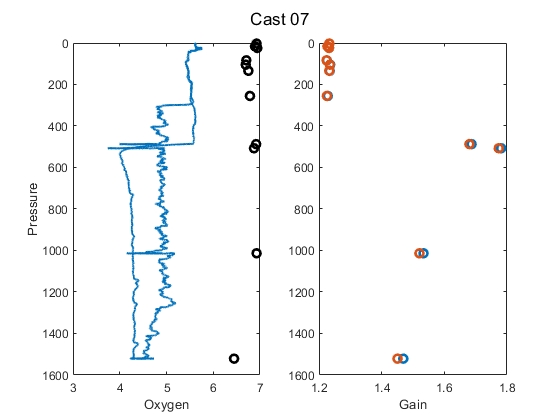

Gain = 1.3715+/- 0.2102
EGain = 1.3668+/- 0.20635


E = cal.E;
E2 = 3.83e-2;
btlsum07 = CTD_Gain_KF(btlsum07,cast07,'Cast 07',E,E2);

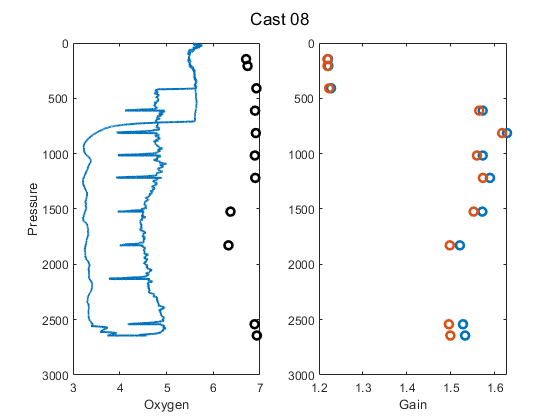

Gain = 1.4714+/- 0.1623
EGain = 1.4564+/- 0.15588


btlsum08 = CTD_Gain_KF(btlsum08,cast08,'Cast 08',E,E2);

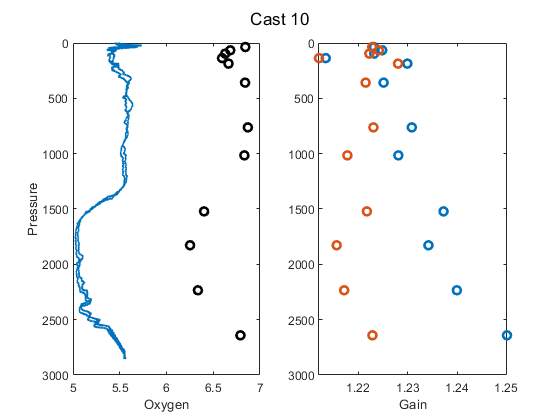

Gain = 1.23+/- 0.0095338
EGain = 1.2207+/- 0.0043404


btlsum10 = CTD_Gain_KF(btlsum10,cast10,'Cast 10',E,E2);

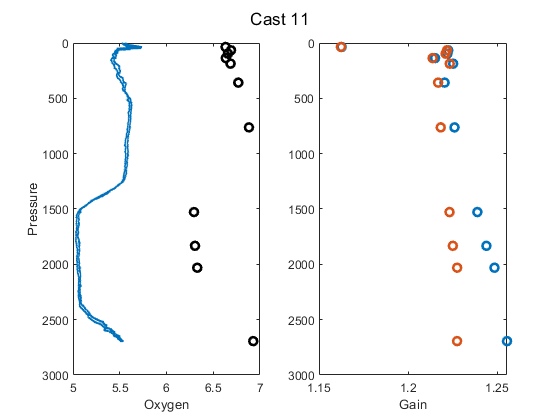

Gain = 1.2255+/- 0.024571
EGain = 1.2164+/- 0.01843


btlsum11 = CTD_Gain_KF(btlsum11,cast11,'Cast 11',E,E2);

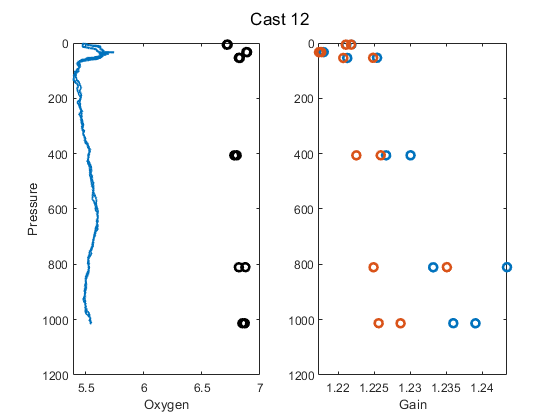

Gain = 1.2278+/- 0.0085353
EGain = 1.2238+/- 0.0048931


btlsum12 = CTD_Gain_KF(btlsum12,cast12,'Cast 12',E,E2);

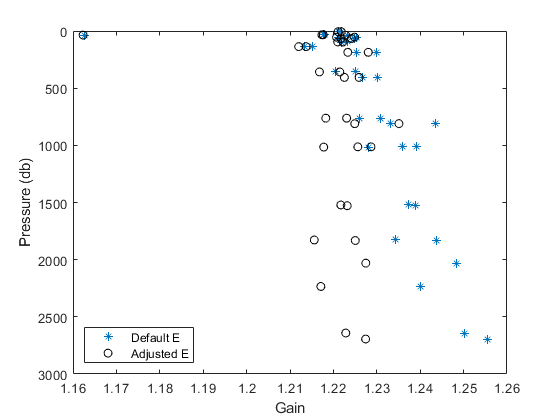

btlsum = [btlsum10; btlsum11; btlsum12];

depth_cut = 500;

figure
plot(btlsum.gain,btlsum.PrDM,'*')
hold on
plot(btlsum.Egain,btlsum.PrDM,'ok')
% plot(btlsum.Egain(btlsum.PrDM > depth_cut),btlsum.PrDM(btlsum.PrDM > depth_cut),'ok')
axis ij
ylabel('Pressure (db)')
xlabel('Gain')
legend('Default E','Adjusted E','Location','SW')


disp(['Gain = ' num2str(nanmean(btlsum.gain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.gain(btlsum.PrDM > depth_cut)))])

Gain = 1.239+/- 0.0082355


disp(['EGain = ' num2str(nanmean(btlsum.Egain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.Egain(btlsum.PrDM > depth_cut)))])

EGain = 1.2236+/- 0.0051329


cal.SOCnew = cal.SOC*nanmean(btlsum.Egain(btlsum.PrDM > depth_cut));
disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 0


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term = ' num2str(E2)])

Adjust. E term = 0.0383


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.46124


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.56437
